% Reading the cello and trombone sounds
%soundsc(cello.x, 1/cello.dt);
%soundsc(trombone.x, 1/trombone.dt);

%Calculating the number of samples in cello and trombone
Nc = length(cello.x)

Nc = 9288

Nt = length(trombone.x)

Nt = 9288


%Calculating the time of each instrument
Tc = Nc * cello.dt

Tc = 1.1338

Tt = Nt * trombone.dt

Tt = 1.1338


fprintf('Length of Cello recording: %.4f seconds\n', Tc);

Length of Cello recording: 1.1338 seconds


fprintf('Length of Trombone recording: %.4f seconds\n', Tt);

Length of Trombone recording: 1.1338 seconds


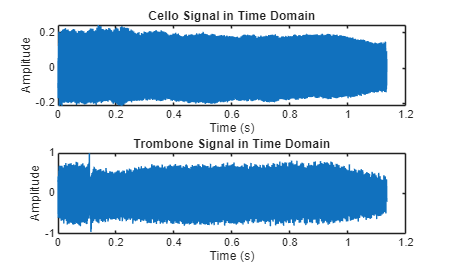

%% Part 2: Frequency Content Analysis
% Plotting the signals in Time Domain
figure('Name', 'Time Domain Signals');
subplot(2,1,1);
plot((0:Nc-1) * cello.dt, cello.x);
title('Cello Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');
subplot(2,1,2);
plot((0:Nt-1) * trombone.dt, trombone.x);
title('Trombone Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');

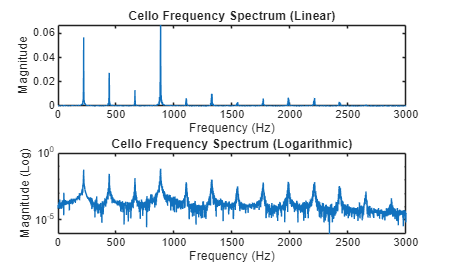



% --- Cello FFT ---
Fs_cello = 1 / cello.dt;                % Sampling frequency            
f_cello = Fs_cello * (0:(Nc/2)) / Nc; % Frequency vector

Y_cello = fft(cello.x);                 % Compute FFT
P2_cello = abs(Y_cello / Nc);      % Two-sided spectrum
P1_cello = P2_cello(1:Nc/2+1);     % Single-sided spectrum
P1_cello(2:end-1) = 2 * P1_cello(2:end-1); 

% --- Trombone FFT ---
Fs_trombone = 1 / trombone.dt;                  
f_trombone = Fs_trombone * (0:(Nt/2)) / Nt; 

Y_trombone = fft(trombone.x);           
P2_trombone = abs(Y_trombone / Nt); 
P1_trombone = P2_trombone(1:Nt/2+1); 
P1_trombone(2:end-1) = 2 * P1_trombone(2:end-1);

% --- Plotting Cello (Linear & Logarithmic) ---
figure('Name', 'Cello Frequency Spectrum');
subplot(2,1,1);
plot(f_cello, P1_cello);
title('Cello Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]); % Zoom in to see the peaks clearly

subplot(2,1,2);
semilogy(f_cello, P1_cello);
title('Cello Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);

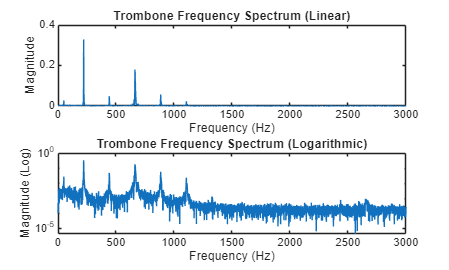


% --- Plotting Trombone (Linear & Logarithmic) ---
figure('Name', 'Trombone Frequency Spectrum');
subplot(2,1,1);
plot(f_trombone, P1_trombone);
title('Trombone Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]);

subplot(2,1,2);
semilogy(f_trombone, P1_trombone);
title('Trombone Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);